## Preliminaries

### Data Selection

% extract session .mat names
listing = dir("3portdata"); 
listing = struct2table(listing);
session_ids = listing.name(~listing.isdir); 

% select only "good" sessions (per Dr. Hyman)
good_sessions = readmatrix("good_sessions.csv"); 
session_ids = string(session_ids(good_sessions));

% extract recorded session ESPs
load("SwitchTrials.mat", "SwTrial"); 
session_esps = SwTrial(good_sessions, 2); 
clear listing good_sessions SwTrial

### Port Inference

Per `hyman2017_reproductions/group.mlx` routine: 

sz = [size(session_ids, 1) 5];
vartypes = ["string" repmat("double", [1 4])]; 
varnames = ["id", "esp", "p25", "p50", "p75"]; 
sessions = table('Size', sz, 'VariableTypes', vartypes, 'VariableNames', varnames); 

for i = 1 : height(sessions)
    load("3portdata/" + session_ids(i), "Event_timestamps"); 
    ports = port_ids(Event_timestamps, 10);

    p25 = find(ismember(ports, "25%"));
    p50 = find(ismember(ports, "50%"));
    p75 = find(ismember(ports, "75%"));
    sessions(i, :) = {session_ids(i), session_esps(i), p25, p50, p75};
    clear i Event_timestamps ports p25 p50 p75
end 
clear sz vartypes varnames session_ids session_esps

## PCA Reproduction: Fig. 2A

Running PCA on iFR data filtered for NP events and averaged over event durations: 

top3_pcs = cell(height(sessions), 4); 
for i = 1 : height(sessions) 
    [filtered_and_avgd_iFRs, np_ports] = filter_and_avg_iFRs(sessions.id(i)); 
    [coeff, score, ~, ~, explained, ~] = pca(filtered_and_avgd_iFRs); 
    top3_pcs{i, 1} = sessions.id(i); 
    top3_pcs{i, 2} = np_ports; 
    top3_pcs{i, 3} = coeff(:, 1:3); 
    top3_pcs{i, 4} = score(:, 1:3); 
    top3_pcs{i, 5} = explained(1:3); 
    clear i filtered_and_avgd_iFRs np_ports coeff score explained
end

top3_pcs = cell2table(top3_pcs, 'VariableNames', ["id", "port_entries", "coeffs", "scores", "var_exp"])

top3_pcs = 12×5 table
                             id                              port_entries        coeffs            scores          var_exp   
    ____________________________________________________    ______________    _____________    ______________    ____________

    "bPFHPC4_12_06_12_iFR10_dur_thin_durs_10ms.mat"         {286×1 double}    {36×3 double}    {286×3 double}    {3×1 double}
    "c7_27_13_H_iFR10_dur_thin_durs_10ms.mat"               {327×1 double}    {64×3 double}    {327×3 double}    {3×1 double}
    "d6_28_13_E_iFR10_withstamps_dur_thin_durs_10ms.mat"    {250×1 double}    {43×3 double}    {250×3 double}    {3×1 double}
    "e7_4_13_E_iFR10ms_dur_thin_durs_10ms.mat"              {260×1 double}    {30×3 double}    {260×3 double}    {3×1 double}
    "f7_19_13_H_iFR10ms_dur_thin_durs_10ms.mat"    

Comparing average variances explained by each PC to reported values: 

explained = zeros(height(sessions), 3); 
for i = 1 : height(sessions)
    explained(i, :) = top3_pcs.var_exp{i}'; 
end

disp("Average var. explained by PC1: " + mean(explained(:, 1)) + "; reported 9.72%")

Average var. explained by PC1: 25.183; reported 9.72%


disp("Average var. explained by PC2: " + mean(explained(:, 2)) + "; reported 5.93%")

Average var. explained by PC2: 14.0294; reported 5.93%


disp("Average var. explained by PC3: " + mean(explained(:, 3)) + "; reported 5.17%")

Average var. explained by PC3: 9.6469; reported 5.17%



total = sum(mean(explained, 1)); 
disp("Total var. explained by top 3 PCs: " + total + "; reported 20.8%")

Total var. explained by top 3 PCs: 48.8593; reported 20.8%


clear i explained total 

Faceting PCA scores by port contingency for visualization:

scores_by_port = cell(height(sessions), 4); 
for i = 1 : height(sessions)
    scores_by_port{i, 1} = sessions.id(i); 
    [sbp25_sm, sbp50_sm, sbp75_sm] = score_by_port(i, sessions, top3_pcs);
    scores_by_port{i, 2} = sbp25_sm; 
    scores_by_port{i, 3} = sbp50_sm; 
    scores_by_port{i, 4} = sbp75_sm; 
    clear i sbp25_sm sbp50_sm sbp75_sm
end
scores_by_port = cell2table(scores_by_port, 'VariableNames', ["id", "sbp25", "sbp50", "sbp75"])

scores_by_port = 12×4 table
                             id                                 sbp25             sbp50             sbp75     
    ____________________________________________________    ______________    ______________    ______________

    "bPFHPC4_12_06_12_iFR10_dur_thin_durs_10ms.mat"         { 96×3 double}    { 95×3 double}    { 95×3 double}
    "c7_27_13_H_iFR10_dur_thin_durs_10ms.mat"               {110×3 double}    {109×3 double}    {108×3 double}
    "d6_28_13_E_iFR10_withstamps_dur_thin_durs_10ms.mat"    { 83×3 double}    { 83×3 double}    { 84×3 double}
    "e7_4_13_E_iFR10ms_dur_thin_durs_10ms.mat"              { 87×3 double}    { 87×3 double}    { 86×3 double}
    "f7_19_13_H_iFR10ms_dur_thin_durs_10ms.mat"             { 98×3 double}    { 98×3 double}    { 99×3 double}
    "hCW8_11_23_12_iFR10ms_dur_thin_durs_10ms.mat"        

Visualizing smoothed trajectories of neural activity in top 3 PC space, faceted by port contingency: 

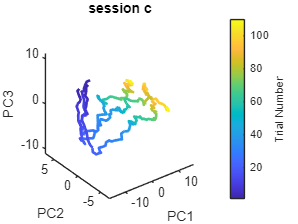

session_id = 2;
window = 20; 
plot_smooth_trajectories(session_id, window, scores_by_port)